# Labolatorium 3 - Modulacja amplitudy, Demodulacja dla AM, DSB AM i SSB AM 

Definiujemy nośną jako $c=A_c \textrm{∙}\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi f_c t\right)$ oraz sygnały modulujące jako  $m_1 =A_m \textrm{∙}\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi f_m t\right)$  m2 - sygnał prostokątny (przeskok fazy, K<-1) $m_3 =A_m \textrm{∙}\sum_{i=1}^{10} \mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi it\right)$

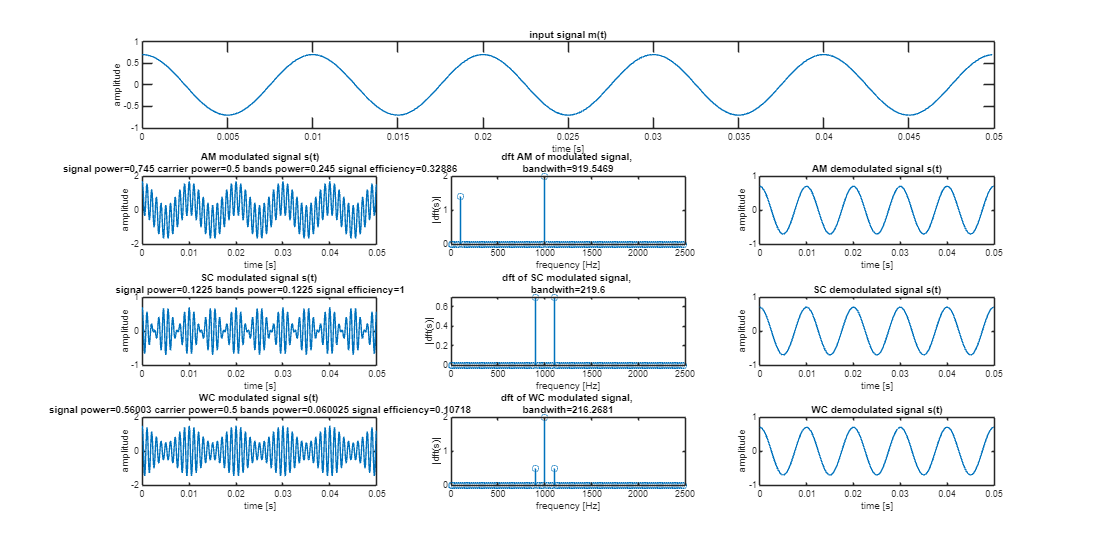

%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.7;
fm = 100;
K = -0.8;

k = Am / Ac;

%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);
c_rms = rms(c)^2;

%---------------------definicja m1-----------------------------


m1 = Am *cos(2*pi*fm*t);


s1_m1 = c + m1;
s1_m1_fft = fft(s1_m1);
s1_m1_BW = obw(s1_m1, fs);
s1_m1_rms = rms(s1_m1)^2;
s1_m1_bands_rms = s1_m1_rms - c_rms;
s1_m1_eff = s1_m1_bands_rms / s1_m1_rms;
s1_m1_demodulated = s1_m1 - c;


s2_m1 = c .* m1;
s2_m1_fft = fft(s2_m1);
s2_m1_BW = obw(s2_m1, fs);
s2_m1_rms = rms(s2_m1)^2;
s2_m1_bands_rms = s2_m1_rms;
s2_m1_eff = s2_m1_bands_rms / s2_m1_rms;
s2_m1_demodulated = s2_m1 ./ c;


s3_m1 = c .* (1 + m1*k);
s3_m1_fft = fft(s3_m1);
s3_m1_BW = obw(s3_m1, fs);
s3_m1_rms = rms(s3_m1)^2;
s3_m1_bands_rms = s3_m1_rms - c_rms;
s3_m1_eff = s3_m1_bands_rms / s3_m1_rms;
s3_m1_demodulated = (s3_m1 - c) ./ (c*k);



%---------------------definicja m2-----------------------------


m2 = [ones(1, length(t)/2), K * ones(1, length(t)/2)];
m2_rms = rms(m2)^2;

s1_m2 = c + m2;
s1_m2_fft = fft(s1_m2);
s1_m2_BW = obw(s1_m2, fs);
s1_m2_rms = rms(s1_m2)^2;
s1_m2_bands_rms = s1_m2_rms - c_rms;
s1_m2_eff = s1_m2_bands_rms / s1_m2_rms;
s1_m2_demodulated = s1_m2 - c;


s2_m2 = c .* m2;
s2_m2_fft = fft(s2_m2);
s2_m2_BW = obw(s2_m2, fs);
s2_m2_rms = rms(s2_m2)^2;
s2_m2_bands_rms = s2_m2_rms;
s2_m2_eff = s2_m2_bands_rms / s2_m2_rms;
s2_m2_demodulated = s2_m2 ./ c;

s3_m2 = c .* (1 + m2*k);
s3_m2_fft = fft(s3_m2);
s3_m2_BW = obw(s3_m2, fs);
s3_m2_rms = rms(s3_m2)^2;
s3_m2_bands_rms = s3_m2_rms - c_rms;
s3_m2_eff = s3_m2_bands_rms / s3_m2_rms;
s3_m2_demodulated = (s3_m2 - c) ./ (c*k);

%---------------------definicja m3-----------------------------
m3 = 0;
for i = 1:10
    m3 = m3 + Am * cos(2*pi*fm*i*t);
end
m3_rms = rms(m3)^2;

s1_m3 = c + m3;
s1_m3_fft = fft(s1_m3);
s1_m3_BW = obw(s1_m3, fs);
s1_m3_rms = rms(s1_m3)^2;
s1_m3_bands_rms = s1_m3_rms - c_rms;
s1_m3_eff = s1_m3_bands_rms / s1_m3_rms;
s1_m3_demodulated = s1_m3 - c;


s2_m3 = c .* m3;
s2_m3_fft = fft(s2_m3);
s2_m3_BW = obw(s2_m3, fs);
s2_m3_rms = rms(s2_m3)^2;
s2_m3_bands_rms = s2_m3_rms;
s2_m3_eff = s2_m3_bands_rms / s2_m3_rms;
s2_m3_demodulated = s2_m3 ./ c;

s3_m3 = c .* (1 + m3*k);
s3_m3_fft = fft(s3_m3);
s3_m3_BW = obw(s3_m3, fs);
s3_m3_rms = rms(s3_m3)^2;
s3_m3_bands_rms = s3_m3_rms - c_rms;
s3_m3_eff = s3_m3_bands_rms / s3_m3_rms;
s3_m3_demodulated = (s3_m3 - c) ./ (c*k);


fig = figure;
fig.Position = [0, 0, 2000, 1000];
subplot(4, 3, [1,2,3])
plot(t, m1)
title('input signal m(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 4)
plot(t, s1_m1)
title(['AM modulated signal s(t)', newline, 'signal power=', num2str(s1_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m1_bands_rms), ' signal efficiency=', num2str(s1_m1_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4,3,5)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m1_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,6)
plot(t, s1_m1_demodulated)
title(['AM demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 7)
plot(t, s2_m1)
title(['SC modulated signal s(t) ', newline, 'signal power=', num2str(s2_m1_rms),' bands power=', num2str(s2_m1_bands_rms), ' signal efficiency=', num2str(s2_m1_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4,3,8)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m1_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,9)
plot(t, s2_m1_demodulated)
title(['SC demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 10)
plot(t, s3_m1)
title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m1_bands_rms), ' signal efficiency=', num2str(s3_m1_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4,3,11)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m1_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,12)
plot(t, s3_m1_demodulated)
title(['WC demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')

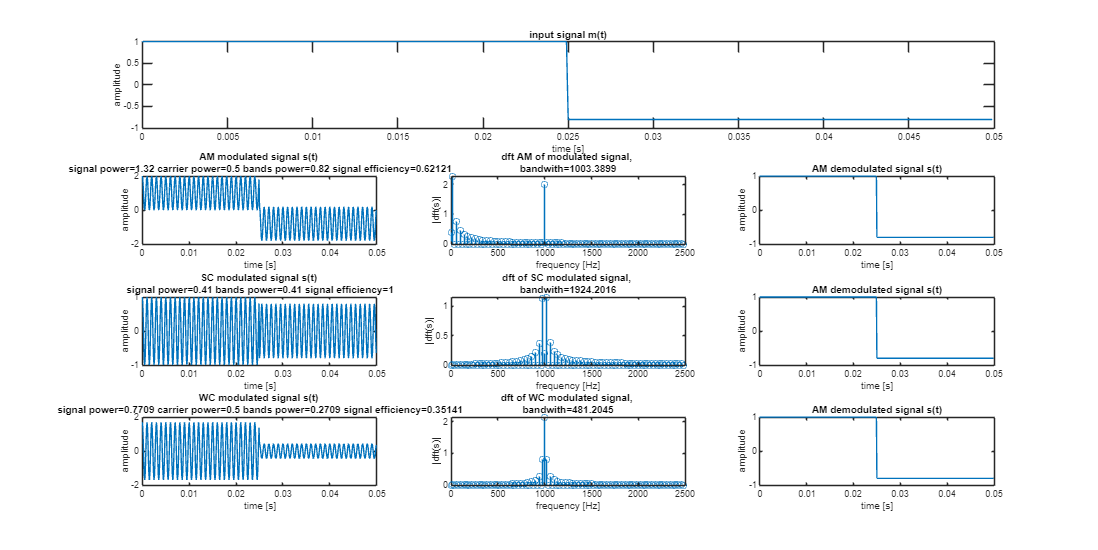



fig = figure;
fig.Position = [0, 0, 2000, 1000];
subplot(4, 3, [1,2,3])
plot(t, m2)
title('input signal m(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 4)
plot(t, s1_m2)
title(['AM modulated signal s(t) ',newline, 'signal power=', num2str(s1_m2_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m2_bands_rms), ' signal efficiency=', num2str(s1_m2_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4,3,5)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s1_m2_fft(1:length(t)/4)/length(k)))
title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m2_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,6)
plot(t, s1_m2_demodulated)
title(['AM demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 7)
plot(t, s2_m2)
title(['SC modulated signal s(t) ',newline, 'signal power=', num2str(s2_m2_rms),' bands power=', num2str(s2_m2_bands_rms), ' signal efficiency=', num2str(s2_m2_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3,8)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s2_m2_fft(1:length(t)/4)/length(k)))
title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m2_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,9)
plot(t, s2_m2_demodulated)
title(['AM demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 10)
plot(t, s3_m2)
title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m2_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m2_bands_rms), ' signal efficiency=', num2str(s3_m2_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3,11)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s3_m2_fft(1:length(t)/4)/length(k)))
title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m2_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,12)
plot(t, s3_m2_demodulated)
title(['AM demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')

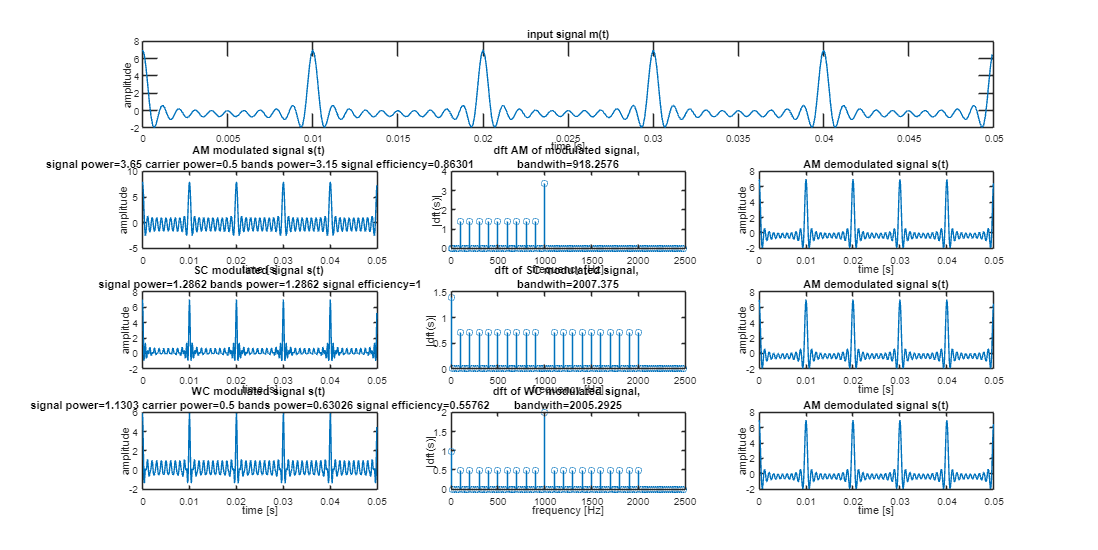




fig = figure;
fig.Position = [0, 0, 2000, 1000];
subplot(4, 3, [1,2,3])
plot(t, m3)
title('input signal m(t)')
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 4)
plot(t, s1_m3)
title(['AM modulated signal s(t) ',newline, 'signal power=', num2str(s1_m3_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m3_bands_rms), ' signal efficiency=', num2str(s1_m3_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3,5)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s1_m3_fft(1:length(t)/4)/length(k)))
title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m3_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,6)
plot(t, s1_m3_demodulated)
title(['AM demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 7)
plot(t, s2_m3)
title(['SC modulated signal s(t) ',newline, 'signal power=', num2str(s2_m3_rms),' bands power=', num2str(s2_m3_bands_rms), ' signal efficiency=', num2str(s2_m3_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3,8)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s2_m3_fft(1:length(t)/4)/length(k)))
title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m3_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,9)
plot(t, s2_m3_demodulated)
title(['AM demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3, 10)
plot(t, s3_m3)
title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m3_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m3_bands_rms), ' signal efficiency=', num2str(s3_m3_eff)])
xlabel('time [s]')
ylabel('amplitude')
subplot(4, 3,11)
k = 0:(length(t)/4)-1;
stem(k*0.25*fs/length(k), abs(s3_m3_fft(1:length(t)/4)/length(k)))
title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m3_BW)])
xlabel('frequency [Hz]')
ylabel('|dft(s)|')
subplot(4,3,12)
plot(t, s3_m3_demodulated)
title(['AM demodulated signal s(t)'])
xlabel('time [s]')
ylabel('amplitude')